# `实验 交通标志的识别`

clc; % 清空命令行
clear all; % 清除工作区中的所有变量
close all; % 关闭所有图形窗口

## 1 构建训练集和测试集

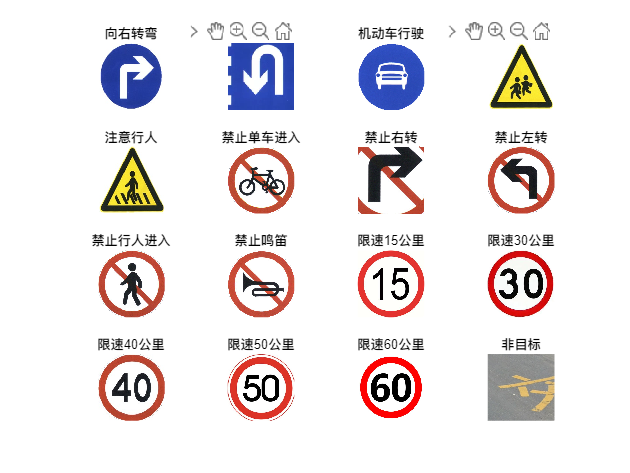

data_path = '../imgs/traffic_sign_dataset'; % 数据的根路径
sign_example_path = '../imgs/traffic_sign_example';
train_data_path = fullfile(data_path, ''); % 训练数据路径，这里没有具体的文件夹名

% 获取目录列表
files_list = dir(data_path);

% 过滤掉'.'和'..'条目，并提取文件夹名称
class_name = {files_list([files_list.isdir] & ~ismember({files_list.name}, {'.', '..'})).name};

% 可视化一下每个类别
figure
for i = 1:numel(class_name)
    subplot(4,4,i);
    imshow(imread(fullfile(sign_example_path, [class_name{i} '.jpg'])))
    title(class_name{i})
end

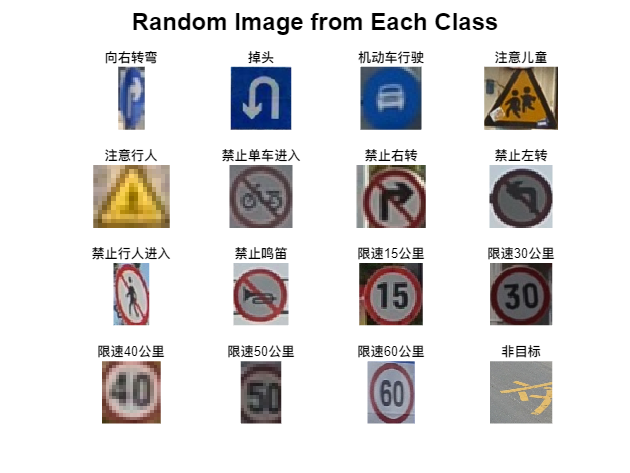

% 新建一个图像显示
figure;

% 遍历每个类别，随机选择一张图片显示
for i = 1:numel(class_name)
    % 获取当前类别文件夹中所有图片的列表
    class_folder = fullfile(data_path, class_name{i});
    class_images = dir(fullfile(class_folder, '*.png')); % 假设图片格式为 jpg
    
    % 随机选择一张图片
    if ~isempty(class_images)
        random_idx = randi(numel(class_images));  % 随机选择索引
        image_filename = fullfile(class_folder, class_images(random_idx).name);
        
        % 读取并显示图片
        subplot(4, 4, i);
        imshow(imread(image_filename));
        title(class_name{i}, 'Interpreter', 'none'); % 显示类别名称，不解释特殊字符
        
    else
        % 如果文件夹中没有图片，显示错误信息
        subplot(4, 4, i);
        text(0.5, 0.5, 'No images found', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        title(class_name{i}, 'Interpreter', 'none');
    end
end

% 设置子图布局
sgtitle('Random Image from Each Class', 'FontSize', 16, 'FontWeight', 'bold'); % 设置总标题

## 2 对训练集和测试集所有图像提取梯度直方图特征

train_features = []; % 用于存储训练特征的数组
train_labels = []; % 用于存储训练标签的数组

test_features = []; % 用于存储测试特征的数组
test_labels = []; % 用于存储测试标签的数组

idx = 0; % 索引计数器

% 训练部分
for index = 1:length(class_name)
    % 正在处理的类索引
    disp(['Processing class -- ', class_name{index}]);

    % 处理每个类的数据
    class_data = fullfile(train_data_path, class_name{index});
    img_list = dir(class_data); % 获取特定类的所有图像文件列表
    
    % 过滤出图像文件
    img_list = img_list(~ismember({img_list.name}, {'.', '..'}));
    
    % 为当前类生成相应数量的标签
    current_labels = index * ones(size(img_list, 1), 1);

    % 从当前类别中随机选择10%作为测试集
    num_images = length(img_list);
    test_indices = randsample(num_images, floor(0.1 * num_images));

    for i = 1:length(img_list)
        idx = idx + 1;
        % 获取图像路径并读取图像
        image_path = fullfile(class_data, img_list(i).name);
        image = imread(image_path);

        % 调整图像大小
        resize_image = imresize(image, [256 256]);

        % 提取HOG特征
        hog_features = extractHOGFeatures(resize_image, 'CellSize', [5 5]);

        % 决定是添加到训练集还是测试集
        if any(i == test_indices)
            % 添加到测试集
            test_features = [test_features; hog_features];
            test_labels = [test_labels; current_labels(i)];
        else
            % 添加到训练集
            train_features = [train_features; hog_features];
            train_labels = [train_labels; current_labels(i)];
        end
    end
end

Processing class -- 向右转弯
Processing class -- 掉头
Processing class -- 机动车行驶
Processing class -- 注意儿童
Processing class -- 注意行人
Processing class -- 禁止单车进入
Processing class -- 禁止右转
Processing class -- 禁止左转
Processing class -- 禁止行人进入
Processing class -- 禁止鸣笛
Processing class -- 限速15公里
Processing class -- 限速30公里
Processing class -- 限速40公里
Processing class -- 限速50公里
Processing class -- 限速60公里
Processing class -- 非目标


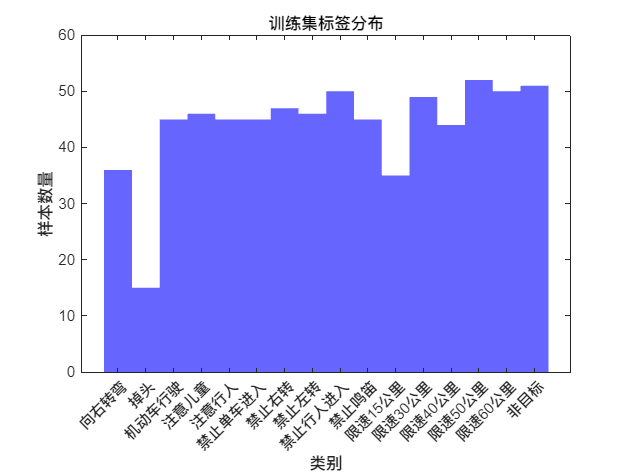

% 获取类别数量
num_classes = length(class_name);

% 训练集标签直方图
figure;
histogram(train_labels, 'Normalization', 'count', 'EdgeColor', 'none', 'FaceColor', 'blue');
title('训练集标签分布');
xlabel('类别');
ylabel('样本数量');
set(gca, 'XTick', 1:num_classes, 'XTickLabel', class_name);
xtickangle(45); % 旋转 x 轴标签，以便显示更清楚

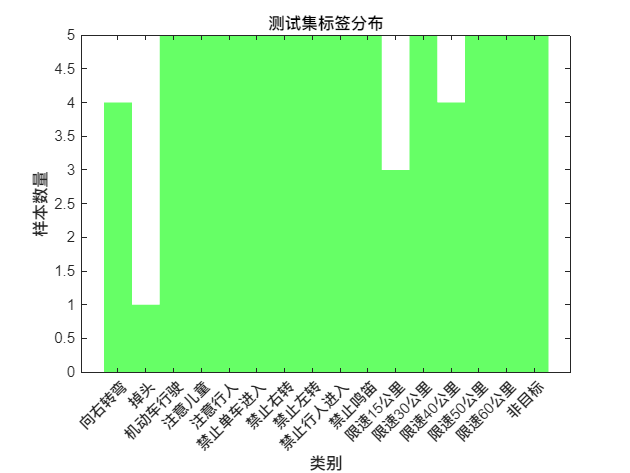


% 测试集标签直方图
figure;
histogram(test_labels, 'Normalization', 'count', 'EdgeColor', 'none', 'FaceColor', 'green');
title('测试集标签分布');
xlabel('类别');
ylabel('样本数量');
set(gca, 'XTick', 1:num_classes, 'XTickLabel', class_name);
xtickangle(45); % 旋转 x 轴标签，以便显示更清楚

## 3 利用HOG特征训练SVM分类模型

% 训练SVM分类器
tic
classifier = fitcecoc(train_features,train_labels);
toc

历时 36.600641 秒。


## 4 评价SVM分类模型性能

% 使用训练数据进行预测
predicted_labels = predict(classifier, test_features);

% 计算训练集的分类精度
accuracy_train = sum(predicted_labels == test_labels) / numel(test_labels);
disp(['Test Accuracy: ', num2str(accuracy_train)]);

Test Accuracy: 0.91667


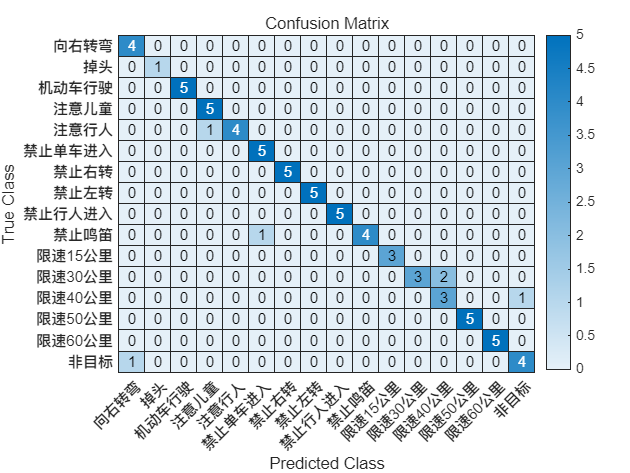

% 计算混淆矩阵
C = confusionmat(test_labels, predicted_labels);

% 可视化混淆矩阵
figure;
heatmap(class_name, class_name, C);
xlabel('Predicted Class');
ylabel('True Class');
title('Confusion Matrix');

## 5 测试与交通标志定位部分对接

上面的都封装了一下

% 数据的根路径
data_path = '../imgs/traffic_sign_dataset'; % 数据的根路径

% 获取目录列表
files_list = dir(data_path);

% 过滤掉'.'和'..'条目，并提取文件夹名称
class_name = {files_list([files_list.isdir] & ~ismember({files_list.name}, {'.', '..'})).name}

% 重新创建数据集，不划分测试集
[train_features, train_labels, test_features, test_labels] = createDataSet(class_name, data_path, 0);

% 训练SVM分类器
tic
classifier = fitcecoc(train_features,train_labels);
toc
save classifier

% 打开对话框选择测试图片路径
pic_dir = uigetdir('./imgs', '选择文件夹');
if pic_dir == 0
    disp('没有选择任何文件夹');
    return;
end

% 获取所有图像文件列表
img_list = dir(fullfile(pic_dir, '*.jpg'));

for i = 1:length(img_list)
    % 初始化标签
    predictedLabels = {};
    
    file_name = img_list(i).name;
    disp(['Predicting for ', img_list(i).name]); % 打印当前正在处理的文件名
    
    % 获取图像路径并读取图像
    image_path = fullfile(pic_dir, img_list(i).name);
    img = imread(image_path); 

     % 获取标志
    [~, signs] = Detection(img);
    
    % 调整图像大小
    resize_signs = cell(size(signs));

    % 标志数量
    sign_num = size(signs,2);
    
    for i = 1:numel(signs)
        % 读取当前的标志图像
        sign_image = signs{i};
        
        % 调整图像大小
        resize_signs{i} = imresize(sign_image, [256 256]);

        % 提取HOG特征并进行分类
        test_features = extractHOGFeatures(resize_signs{i}, 'CellSize', [5 5]);
        label = class_name{predict(classifier, test_features)};   
        predictedLabels{i} = label;
    end
    
    % 可视化
    figure
    subplot(1,sign_num+1,1)
    imshow(imresize(img, [256 256]))
    title("原始图像")
    for k = 1:sign_num
        subplot(1,sign_num+1,k+1)
        imshow(resize_signs{k})
        title(predictedLabels{k})
    end
end